## SET PATH

addpath('data'); addpath('lmutilities');

## Load Dataset 

[train_data, test_data] = DataLoader();

Datafile: "codedimagedata.xlsx" has been loaded!


Datafile: "codedimagedata.xlsx" has been loaded!


## Choose your model

Model = Linear;

## Hyperparameter Initialization

You can play with the step size by moving the slider and see how it affect the learning 

Step =0.1;
searchdirection = 'Lbfgs'; 
StepSizeMode = 'Auto-Stepsize';
LearningMode = 'Batch (off-line)';
adaptive_maxiterations =100;
batch_maxiterations = 300;
constants = Model.Initialize(Step, searchdirection, StepSizeMode, LearningMode,...
    adaptive_maxiterations, batch_maxiterations);

## Train the model

*Training might take a few minutes to complete*

Iteration (Lbfgs) #1, Inner-Cycle = 1, Stepsize-Cycle = 2, Stepsize = 0.5, Error = 0.0054593, |grad| = 0.0055281, Angle = 8.015e-05 degrees
Iteration (Lbfgs) #2, Inner-Cycle = 2, Stepsize-Cycle = 1, Stepsize = 1, Error = 0.005407, |grad| = 0.005201, Angle = 14.8937 degrees


Iteration (Lbfgs) #3, Inner-Cycle = 3, Stepsize-Cycle = 1, Stepsize = 1, Error = 0.0046216, |grad| = 0.022579, Angle = 2.4813 degrees


Iteration (Lbfgs) #4, Inner-Cycle = 4, Stepsize-Cycle = 1, Stepsize = 1, Error = 0.0022762, |grad| = 0.012566, Angle = 74.6891 degrees


Iteration (Lbfgs) #5, Inner-Cycle = 0, Stepsize-Cycle = 1, Stepsize = 1, Error = 0.0021979, |grad| = 0.01067, Angle = 80.1667 degrees


Iteration (Lbfgs) #6, Inner-Cycle = 1, Stepsize-Cycle = 1, Stepsize = 1, Error = 0.0021976, |grad| = 0.010969, Angle = 0.00034814 degrees


Iteration (Lbfgs) #7, Inner-Cycle = 2, Stepsize-Cycle = 1, Stepsize = 1, Error = 0.0021658, |grad| = 0.00094266, Angle = 0.75495 degrees


Iteration (Lbfgs) #8, Inner-Cycle = 3, Stepsize-Cycle = 1, Stepsize = 1, Error = 0.0021631, |grad| = 0.00092192, Angle = 0.36633 degrees


Iteration (Lbfgs) #9, Inner-Cycle = 4, Stepsize-Cycle = 1, Stepsize = 1, Error = 0.0020287, |grad| = 0.0092975, Angle = 11.4212 degrees


Iteration (Lbfgs) #10, Inner-Cycle = 0, Stepsize-Cycle = 1, Stepsize = 1, Error = 0.0016419, |grad| = 0.0041074, Angle = 81.4868 degrees


Iteration (Lbfgs) #11, Inner-Cycle = 1, Stepsize-Cycle = 1, Stepsize = 1, Error = 0.0016414, |grad| = 0.0044531, Angle = 0.00055024 degrees


Iteration (Lbfgs) #12, Inner-Cycle = 2, Stepsize-Cycle = 1, Stepsize = 1, Error = 0.0016362, |grad| = 0.00068586, Angle = 2.2262 degrees


Iteration (Lbfgs) #13, Inner-Cycle = 3, Stepsize-Cycle = 1, Stepsize = 1, Error = 0.0016353, |grad| = 0.00071236, Angle = 0.75237 degrees


Iteration (Lbfgs) #14, Inner-Cycle = 4, Stepsize-Cycle = 1, Stepsize = 1, Error = 0.0016148, |grad| = 0.0034007, Angle = 17.1152 degrees


Iteration (Lbfgs) #15, Inner-Cycle = 0, Stepsize-Cycle = 1, Stepsize = 1, Error = 0.0015735, |grad| = 0.00040051, Angle = 77.5081 degrees


Iteration (Lbfgs) #16, Inner-Cycle = 1, Stepsize-Cycle = 1, Stepsize = 1, Error = 0.0015734, |grad| = 0.00046668, Angle = 0.0015245 degrees


Iteration (Lbfgs) #17, Inner-Cycle = 2, Stepsize-Cycle = 1, Stepsize = 1, Error = 0.0015731, |grad| = 0.00033255, Angle = 44.1023 degrees


Iteration (Lbfgs) #18, Inner-Cycle = 3, Stepsize-Cycle = 1, Stepsize = 1, Error = 0.0015637, |grad| = 0.002072, Angle = 38.5856 degrees


Iteration (Lbfgs) #19, Inner-Cycle = 4, Stepsize-Cycle = 1, Stepsize = 1, Error = 0.0015547, |grad| = 0.00086909, Angle = 82.3513 degrees


Iteration (Lbfgs) #20, Inner-Cycle = 0, Stepsize-Cycle = 1, Stepsize = 1, Error = 0.0015543, |grad| = 0.00034429, Angle = 82.4973 degrees


Iteration (Lbfgs) #21, Inner-Cycle = 1, Stepsize-Cycle = 1, Stepsize = 1, Error = 0.0015542, |grad| = 0.00029516, Angle = 0.0017398 degrees


Iteration (Lbfgs) #22, Inner-Cycle = 2, Stepsize-Cycle = 1, Stepsize = 1, Error = 0.0015541, |grad| = 0.00024072, Angle = 45.1768 degrees


Iteration (Lbfgs) #23, Inner-Cycle = 3, Stepsize-Cycle = 1, Stepsize = 1, Error = 0.0015472, |grad| = 0.00024713, Angle = 43.1426 degrees


Iteration (Lbfgs) #24, Inner-Cycle = 4, Stepsize-Cycle = 1, Stepsize = 1, Error = 0.0015472, |grad| = 0.00024169, Angle = 79.1795 degrees


Iteration (Lbfgs) #25, Inner-Cycle = 0, Stepsize-Cycle = 1, Stepsize = 1, Error = 0.0015472, |grad| = 7.6622e-05, Angle = 48.2662 degrees


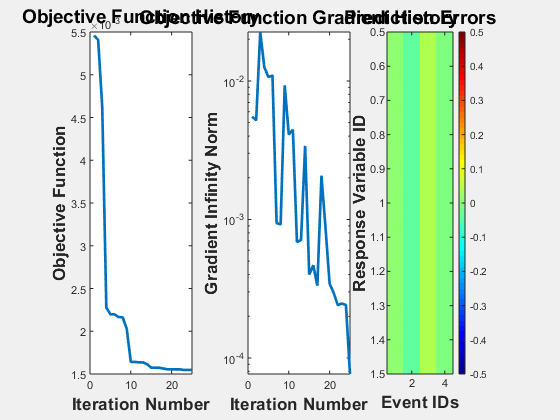

[parameters,performancehistory, sazout, varnames] = Model.train(train_data, constants);

## Model Statistics & Mispecification Analysis

Model.display_statistics(performancehistory, sazout)

----------------------------Model Statistics------------------------------
  
Number of iterations = 25                                 
Objective Function Value = 0.0015472                      
Gradient Infinity Norm (convergence criteria) = 7.6622e-05
Hessian Condition Number (local minimum test) = 2039.2435 
Largest Eigenvalue = 2.0392                               
  
  
----------------------Model Misspecification Check------------------------
  
Information Matrix Scores:
OPG Condition Number = NaN
Hessian Condition Number = 2039.2435
tr(inv(a)b) = 0.0032422, tr(inv(b)a) = 0.0032422, det(inv(a)b) = 2.5637e-200
 
--------------------------------------------------------------------------


## Model Parameter Estimates

Model.parameter_estimates(sazout, varnames, parameters)

 
f2 Beta = 0.071474, Z=0.37343, p=0.70883
f3 Beta = -0.020497, Z=-0.42878, p=0.66808
f4 Beta = -0.012414, Z=-0.13448, p=0.89302
f5 Beta = 0.14897, Z=0.79842, p=0.42463
f6 Beta = 0.1409, Z=1.4592, p=0.1445
f7 Beta = 0.14172, Z=1.2519, p=0.2106
f8 Beta = 0.06715, Z=0.76171, p=0.44623
f9 Beta = -0.12075, Z=-4.6946, p=2.6714e-06
f10 Beta = 0.071724, Z=1.8046, p=0.071142
f11 Beta = 0.16302, Z=7.5453, p=4.5075e-14
f12 Beta = 0.048889, Z=3.261, p=0.0011101
f13 Beta = 0.10347, Z=1.5523, p=0.12059
f14 Beta = 0.072689, Z=0.54263, p=0.58738
Intercept Beta = -0.030344, Z=-1.1762, p=0.23952


## Prediction Performance 

**On Train data **

Model.predict(parameters,constants,train_data)

 SAMPLE SIZE = 4
 CONVERGENCE: Final Grad Norm = 0.20313
 PREDICTION ERROR = 0.015712
% Correct = 89.9225%, Precision=0%, Recall = 0%
 UNIQUENESS: Condition Number = 2039.2435, Max. Hess Eigenvalue = 2.0392
 OUT-OF-SAMPLE PREDICTION ERROR =0.038766


**On Test Data**

Model.predict(parameters,constants,test_data)

 SAMPLE SIZE = 4
 CONVERGENCE: Final Grad Norm = 0.20313
 PREDICTION ERROR = 0.015712
% Correct = 89.9225%, Precision=0%, Recall = 0%
 UNIQUENESS: Condition Number = 2039.2435, Max. Hess Eigenvalue = 2.0392
 OUT-OF-SAMPLE PREDICTION ERROR =0.038766
